%% FARO 21000 Error Propagation Model
% Based on Hall & Schreve Error Propagation Model:
% Lambda_F = J * Lambda_theta * J'
%
% This live script currently includes only:
% 1. User inputs
% 2. Build DH parameters
% 3. Forward kinematics
% 4. Jacobian calculation
% 5. Error propagation
%
% Units:
% - lengths in mm
% - angles in radians internally
%
% Current working model:
% d = [283, L1, 0, L2, 0, 220]
% a = [0, 0, 0, 0, 0, 0]
% alpha = [90, -90, 90, -90, 90, 0]
%
% Twist angles have been assumed and will be revised later.

clear; clc; close all;

%% 1. User inputs

% FaroArm Quantum 21000, size 3000 mm
L1 = 755;   % mm
L2 = 569;   % mm

% Joint angles [theta1 ... theta6] in degrees
theta_deg = [10, 35, -20, 40, -15, 5];
theta = deg2rad(theta_deg);

% Encoder standard deviation
sigma_theta_arcsec = 6;   % assumed example value
sigma_theta = arcsec2rad_local(sigma_theta_arcsec);

% Independent equal-variance encoder covariance
Lambda_theta = (sigma_theta^2) * eye(6);


%% 2. Build DH parameters

% Simplified corrected model based on your chosen geometry
a = [0 0 0 0 0 0];
d = [283 L1 0 L2 0 220];
alpha_deg = [90 -90 90 -90 90 0];
alpha = deg2rad(alpha_deg);

disp('DH parameters being used:')

DH parameters being used:


table((1:6).', a(:), alpha_deg(:), d(:), ...
    'VariableNames', {'Link','a_mm','alpha_deg','d_mm'})

ans = 6×4 table
    Link    a_mm    alpha_deg    d_mm
    ____    ____    _________    ____

     1       0          90       283 
     2       0         -90       755 
     3       0          90         0 
     4       0         -90       569 
     5       0          90         0 
     6       0           0       220 


%% 3. Forward kinematics

[T06, A_all] = forward_kinematics_local(theta, alpha, a, d);

p = T06(1:3,4);

fprintf('\nProbe tip position [mm]:\n');


Probe tip position [mm]:


fprintf('X = %.4f\n', p(1));

X = 28.0203


fprintf('Y = %.4f\n', p(2));

Y = -1492.2599


fprintf('Z = %.4f\n', p(3));

Z = 76.1976



disp('Overall transformation T06:')

Overall transformation T06:


disp(T06)

   1.0e+03 *

    0.0001   -0.0010   -0.0002    0.0280
   -0.0005    0.0001   -0.0009   -1.4923
    0.0009    0.0002   -0.0004    0.0762
         0         0         0    0.0010



%% 4. Jacobian calculation

J = compute_jacobian_dh_local(theta, alpha, a, d, A_all);

disp('Jacobian J [mm/rad]:')

Jacobian J [mm/rad]:


disp(J)

   1.0e+03 *

    1.4923    0.2037    0.6339    0.0546    0.0495         0
    0.0280    0.0359   -0.2013   -0.0031   -0.1021         0
         0   -0.2315    0.4127   -0.0160    0.1885         0



%% 5. Error propagation

Lambda_F = J * Lambda_theta * J.';
Lambda_F = 0.5 * (Lambda_F + Lambda_F.');

disp('Encoder covariance Lambda_theta [rad^2]:')

Encoder covariance Lambda_theta [rad^2]:


disp(Lambda_theta)

   1.0e-09 *

    0.8462         0         0         0         0         0
         0    0.8462         0         0         0         0
         0         0    0.8462         0         0         0
         0         0         0    0.8462         0         0
         0         0         0         0    0.8462         0
         0         0         0         0         0    0.8462




disp('Probe-tip position covariance Lambda_F [mm^2]:')

Probe-tip position covariance Lambda_F [mm^2]:


disp(Lambda_F)

    0.0023   -0.0001    0.0002
   -0.0001    0.0000   -0.0001
    0.0002   -0.0001    0.0002




[V, D] = eig(Lambda_F);
eigvals = diag(D);
[eigvals, idx] = sort(real(eigvals), 'descend');
V = V(:, idx);

eigvals(eigvals < 0) = 0;
sigma_axes = sqrt(eigvals);

fprintf('\nPrincipal 1-sigma uncertainty axes [mm]:\n');


Principal 1-sigma uncertainty axes [mm]:


fprintf('sigma_1 = %.6f\n', sigma_axes(1));

sigma_1 = 0.047792


fprintf('sigma_2 = %.6f\n', sigma_axes(2));

sigma_2 = 0.015503


fprintf('sigma_3 = %.6f\n', sigma_axes(3));

sigma_3 = 0.002048


%% 6. Pose sweep and uncertainty mapping

% Sweep ranges for the main positioning joints
theta1_list = linspace(-90, 90, 13);   % base rotation
theta2_list = linspace(10, 80, 10);    % shoulder
theta3_list = linspace(-60, 60, 10);   % elbow

% Hold wrist joints fixed for first-pass mapping
theta4_fixed = 0;
theta5_fixed = 0;
theta6_fixed = 0;

N = numel(theta1_list) * numel(theta2_list) * numel(theta3_list);

XYZ = zeros(N,3);
reach_vals = zeros(N,1);
u_max_vals = zeros(N,1);
U95_vals = zeros(N,1);
sigma1_vals = zeros(N,1);
sigma2_vals = zeros(N,1);
sigma3_vals = zeros(N,1);
sigmaR_vals = zeros(N,1);
sigmaT_vals = zeros(N,1);
sigmaZ_vals = zeros(N,1);
anisotropy_vals = zeros(N,1);
angles_deg = zeros(N,6);

idx = 0;

for t1 = theta1_list
    for t2 = theta2_list
        for t3 = theta3_list

            idx = idx + 1;

            theta_deg_i = [t1, t2, t3, theta4_fixed, theta5_fixed, theta6_fixed];
            theta_i = deg2rad(theta_deg_i);

            % Forward kinematics
            [T06_i, A_all_i] = forward_kinematics_local(theta_i, alpha, a, d);
            p_i = T06_i(1:3,4);

            % Jacobian
            J_i = compute_jacobian_dh_local(theta_i, alpha, a, d, A_all_i);

            % Error propagation
            Lambda_F_i = J_i * Lambda_theta * J_i.';
            Lambda_F_i = 0.5 * (Lambda_F_i + Lambda_F_i.');

            % Principal uncertainties
            [V_i, D_i] = eig(Lambda_F_i);
            eigvals_i = diag(D_i);
            eigvals_i = sort(real(eigvals_i), 'descend');
            eigvals_i(eigvals_i < 0) = 0;
            sigma_axes_i = sqrt(eigvals_i);

            % Radial / tangential / vertical directions
            r_xy = norm(p_i(1:2));
            if r_xy > 1e-12
                eR = [p_i(1); p_i(2); 0] / r_xy;
                eT = [-p_i(2); p_i(1); 0] / r_xy;
            else
                eR = [1;0;0];
                eT = [0;1;0];
            end
            eZ = [0;0;1];

            sigmaR = sqrt(max(eR.' * Lambda_F_i * eR, 0));
            sigmaT = sqrt(max(eT.' * Lambda_F_i * eT, 0));
            sigmaZ = sqrt(max(eZ.' * Lambda_F_i * eZ, 0));

            % Store results
            XYZ(idx,:) = p_i.';
            reach_vals(idx) = norm(p_i);
            u_max_vals(idx) = sigma_axes_i(1);
            U95_vals(idx) = 2 * sigma_axes_i(1);
            sigma1_vals(idx) = sigma_axes_i(1);
            sigma2_vals(idx) = sigma_axes_i(2);
            sigma3_vals(idx) = sigma_axes_i(3);
            sigmaR_vals(idx) = sigmaR;
            sigmaT_vals(idx) = sigmaT;
            sigmaZ_vals(idx) = sigmaZ;
            anisotropy_vals(idx) = sigma_axes_i(1) / max(sigma_axes_i(3), eps);
            angles_deg(idx,:) = theta_deg_i;

        end
    end
end

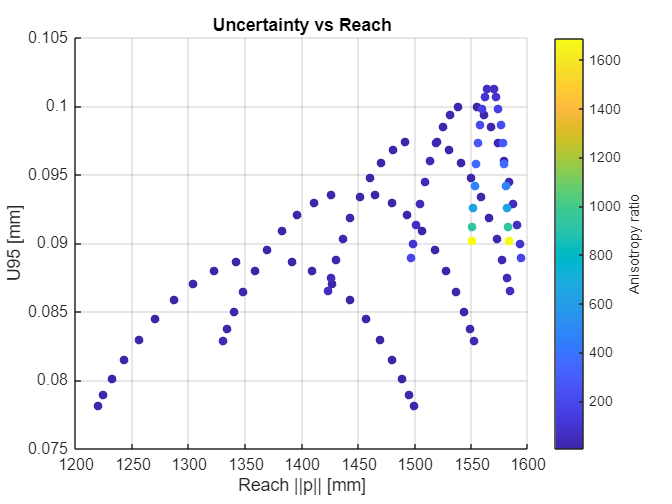

%% 7. Uncertainty plots

% Plot 1: U95 vs reach
figure;
scatter(reach_vals, U95_vals, 30, anisotropy_vals, 'filled');
xlabel('Reach ||p|| [mm]');
ylabel('U95 [mm]');
title('Uncertainty vs Reach');
cb = colorbar;
cb.Label.String = 'Anisotropy ratio';
grid on;

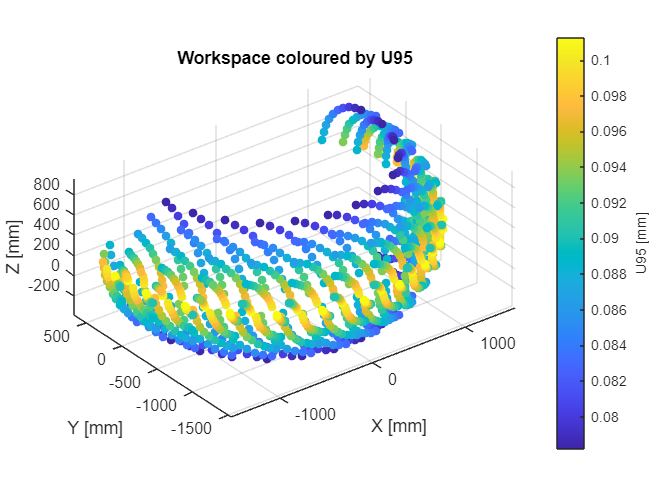


% Plot 2: 3D workspace colored by U95
figure;
scatter3(XYZ(:,1), XYZ(:,2), XYZ(:,3), 30, U95_vals, 'filled');
xlabel('X [mm]');
ylabel('Y [mm]');
zlabel('Z [mm]');
title('Workspace coloured by U95');
cb = colorbar;
cb.Label.String = 'U95 [mm]';
grid on;
axis equal;

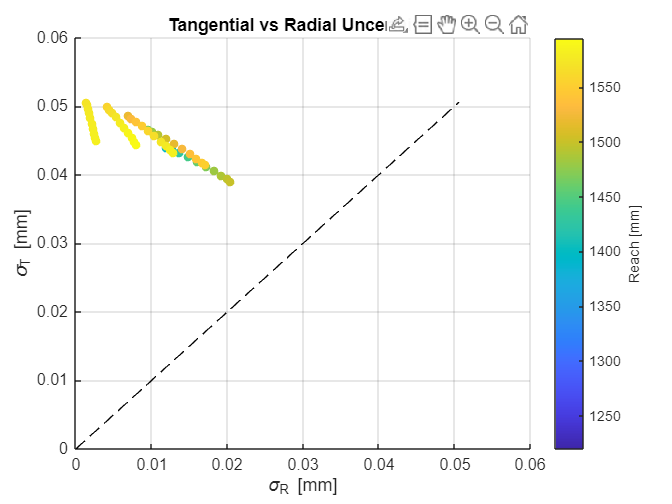


% Plot 3: tangential vs radial uncertainty
figure;
scatter(sigmaR_vals, sigmaT_vals, 30, reach_vals, 'filled');
xlabel('\sigma_R [mm]');
ylabel('\sigma_T [mm]');
title('Tangential vs Radial Uncertainty');
cb = colorbar;
cb.Label.String = 'Reach [mm]';
grid on;
hold on;
mx = max([sigmaR_vals; sigmaT_vals]);
plot([0 mx], [0 mx], '--k');
hold off;

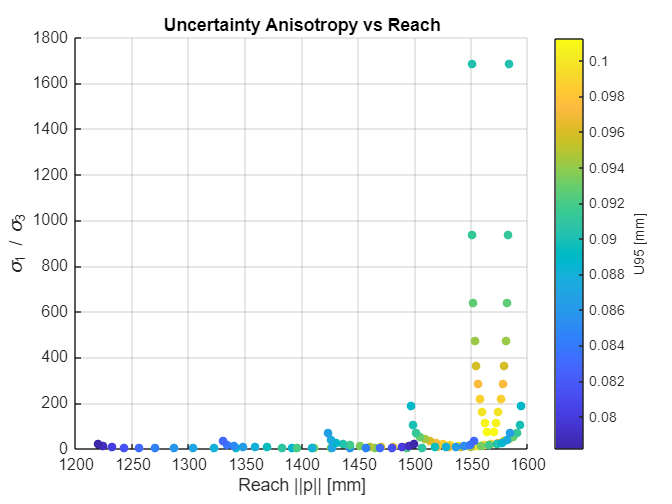


% Plot 4: anisotropy vs reach
figure;
scatter(reach_vals, anisotropy_vals, 30, U95_vals, 'filled');
xlabel('Reach ||p|| [mm]');
ylabel('\sigma_1 / \sigma_3');
title('Uncertainty Anisotropy vs Reach');
cb = colorbar;
cb.Label.String = 'U95 [mm]';
grid on;

%% 8. Summary metrics for TPM interpretation

[maxU95, iMaxU95] = max(U95_vals);
[minU95, iMinU95] = min(U95_vals);
meanU95 = mean(U95_vals);

fprintf('\n--- Workspace uncertainty summary ---\n');


--- Workspace uncertainty summary ---


fprintf('Mean U95 = %.6f mm\n', meanU95);

Mean U95 = 0.091106 mm


fprintf('Max U95  = %.6f mm\n', maxU95);

Max U95  = 0.101257 mm


fprintf('Min U95  = %.6f mm\n', minU95);

Min U95  = 0.078191 mm



fprintf('\nWorst-case pose [deg]: [%s]\n', num2str(angles_deg(iMaxU95,:)));


Worst-case pose [deg]: [-75           10     -6.66667            0            0            0]


fprintf('Worst-case position [mm]: [%.3f %.3f %.3f]\n', ...
    XYZ(iMaxU95,1), XYZ(iMaxU95,2), XYZ(iMaxU95,3));

Worst-case position [mm]: [-1509.583 -311.104 267.094]



fprintf('\nBest-case pose [deg]: [%s]\n', num2str(angles_deg(iMinU95,:)));


Best-case pose [deg]: [-75  80  60   0   0   0]


fprintf('Best-case position [mm]: [%.3f %.3f %.3f]\n', ...
    XYZ(iMinU95,1), XYZ(iMinU95,2), XYZ(iMinU95,3));

Best-case position [mm]: [-1079.622 -412.122 955.913]


%% Local functions
function [T06, A_all] = forward_kinematics_local(theta, alpha, a, d)

    n = numel(theta);
    A_all = cell(1, n);
    T06 = eye(4);

    for i = 1:n
        A_all{i} = A_dh_local(theta(i), alpha(i), a(i), d(i));
        T06 = T06 * A_all{i};
    end
end

function A = A_dh_local(theta, alpha, a, d)

    ct = cos(theta); st = sin(theta);
    ca = cos(alpha); sa = sin(alpha);

    A = [ ct, -st*ca,  st*sa,  a*ct;
          st,  ct*ca, -ct*sa,  a*st;
           0,     sa,     ca,     d;
           0,      0,      0,     1 ];
end

function dA = dA_dtheta_local(theta, alpha, a)

    ct = cos(theta); st = sin(theta);
    ca = cos(alpha); sa = sin(alpha);

    dA = [ -st, -ct*ca,  ct*sa, -a*st;
            ct, -st*ca,  st*sa,  a*ct;
             0,      0,      0,     0;
             0,      0,      0,     0 ];
end

function J = compute_jacobian_dh_local(theta, alpha, a, d, A_all)

    n = numel(theta);
    J = zeros(3, n);

    for i = 1:n
        T_left = eye(4);
        for k = 1:i-1
            T_left = T_left * A_all{k};
        end

        dAi = dA_dtheta_local(theta(i), alpha(i), a(i));

        T_right = eye(4);
        for k = i+1:n
            T_right = T_right * A_all{k};
        end

        dT = T_left * dAi * T_right;
        J(:, i) = dT(1:3, 4);
    end
end

function rad = arcsec2rad_local(arcsec)
    rad = arcsec * pi / (180 * 3600);
end